# [Feature Engineering](https://apmonitor.com/pds/index.php/Main/FeatureEngineering)

Feature engineering is the process of selecting and creating the input descriptors for machine learning. Categorical data is converted to numeric values such as True=1 and False=0. Encoding creates indicators from images, words, numbers, or discrete categories.

- Ordinal Encoding: assign number to each option (e.g. 0=red, 1=blue)

- One-Hot Encoding: new binary (0 or 1) feature for each option

Feature generation may also create new data columns that are derived from the existing features. This may include a nonlinear transform of an individual feature or a product of two features.

Selection and creation of features is an important step in machine learning. Too many features may cause the classifier or regressor to increase the chances of predicting poorly. With many features, one of the inputs may be a bad value and cause a bad prediction. More features also take longer for data curation, training, and prediction. There are methods to rank the most important features for classification or regression.

For more information on feature extraction, see the [feature extraction](https://www.mathworks.com/discovery/feature-extraction.html) MATLAB page.

## Data Transformation

Data transformation is the modification of a data column to create a modified feature.

**Nonlinear Transform**

A common example of data transformation is to perform a nonlinear transform such as log-scale of time.

data = readtable('http://apmonitor.com/pds/uploads/Main/tclab_data6.txt')

data = 3601×5 table
    Time    Q1    Q2     T1       T2  
    ____    __    __    _____    _____

      0     0     0     16.06       16
      1     0     0     16.06    15.97
      2     0     0     16.06    16.03
      3     0     0     16.03       16
      4     0     0     16.03    15.94
      5     0     0     16.06       16
      6     0     0     16.03       16
      7     0     0     16.06    15.94
      8     0     0     16.06    15.97
      9     0     0     16.06    15.97
     10     0     0     16.06    15.94
     11     0     0     16.06    15.97
     12     0     0     16.06    15.97
     13     0     0     16.06    15.94
     14     0     0     16.06    15.94
     15     0     0     16.06    15.94


log_time = log(data.Time) % Make a column for logarithmic Time

log_time =       -Inf
         0
    0.6931
    1.0986
    1.3863
    1.6094
    1.7918
    1.9459
    2.0794
    2.1972


data.log_time = log_time % Join it to the data

data = 3601×6 table
    Time    Q1    Q2     T1       T2      log_time
    ____    __    __    _____    _____    ________

      0     0     0     16.06       16       -Inf 
      1     0     0     16.06    15.97          0 
      2     0     0     16.06    16.03    0.69315 
      3     0     0     16.03       16     1.0986 
      4     0     0     16.03    15.94     1.3863 
      5     0     0     16.06       16     1.6094 
      6     0     0     16.03       16     1.7918 
      7     0     0     16.06    15.94     1.9459 
      8     0     0     16.06    15.97     2.0794 
      9     0     0     16.06    15.97     2.1972 
     10     0     0     16.06    15.94     2.3026 
     11     0     0     16.06    15.97     2.3979 
     12     0     0     16.06    15.97     2.4849 
     13   

head(data)

    Time    Q1    Q2     T1       T2      log_time
    ____    __    __    _____    _____    ________

     0      0     0     16.06       16       -Inf 
     1      0     0     16.06    15.97          0 
     2      0     0     16.06    16.03    0.69315 
     3      0     0     16.03       16     1.0986 
     4      0     0     16.03    15.94     1.3863 
     5      0     0     16.06       16     1.6094 
     6      0     0     16.03       16     1.7918 
     7      0     0     16.06    15.94     1.9459 



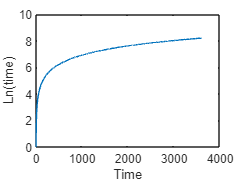


plot(data.log_time)
xlabel('Time')
ylabel('Ln(time)')
hold off;

**Statistical Transform**

Statistical measures are another example of data transformations. A rolling window of the mean, standard deviation, kurtosis, skew, or other statistical information may give additional features for classification or regression.

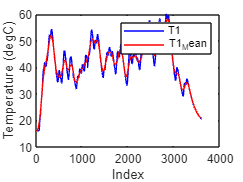

window_size = 100;
data.T1_mean = movmean(data.T1, window_size); % Moving mean of T1
data.T1_stdev = movstd(data.T1, window_size); % Moving standard deviation of T1
data.T1_skew = skewness(data.T1, 0, window_size); % Moving skew of T1

% Plot T1 with its moving mean
plot(data.T1, 'b'); 
hold on;
plot(data.T1_mean, 'r'); 
xlabel('Index');
ylabel('Temperature (degC)');
legend({'T1', 'T1_Mean'});
hold off;

## Categorical Data

Categorical data takes a limited number of discrete values and are typically represented as strings. An example of categorical data is the [classification of cats and dogs](https://apmonitor.com/pds/index.php/Main/KNearestNeighbors) based on weight and color.

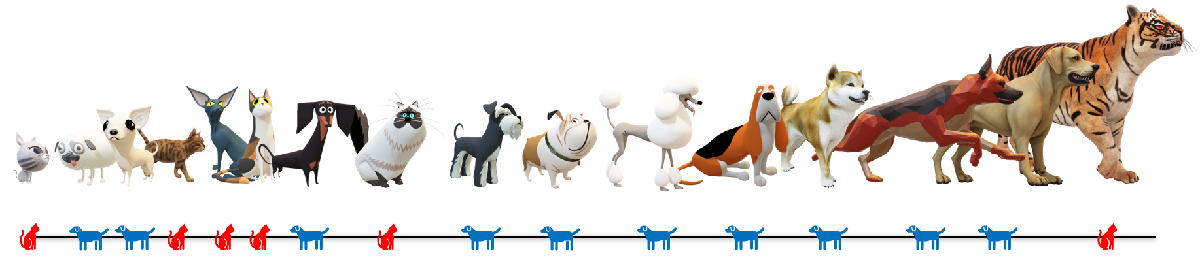

data = readtable('http://apmonitor.com/pds/uploads/Main/animals.txt')
head(data);

data = 16×3 table
    Weight      Color        Type  
    ______    __________    _______

     0.35     {'Gray'  }    {'Cat'}
     0.52     {'White' }    {'Dog'}
     0.73     {'White' }    {'Dog'}
      1.2     {'Orange'}    {'Cat'}
      1.3     {'Gray'  }    {'Cat'}
      1.4     {'Orange'}    {'Cat'}
      2.2     {'Brown' }    {'Dog'}
      2.3     {'White' }    {'Cat'}
        3     {'Gray'  }    {'Dog'}
      4.5     {'Brown' }    {'Dog'}
      8.3     {'White' }    {'Dog'}
     18.2     {'Orange'}    {'Dog'}
     24.4     {'Tan'   }    {'Dog'}
     29.3     {'Orange'}    {'Dog'}
     42.6     {'Tan'   }    {'Dog'}
      220     {'Orange'}    {'Cat'}


    Weight      Color        Type  
    ______    __________    _______

     0.35     {'Gray'  }    {'Cat'}
     0.52     {'White' }    {'Dog'}
     0.73     {'White' }    {'Dog'}
      1.2     {'Orange'}    {'Cat'}
      1.3     {'Gray'  }    {'Cat'}
      1.4     {'Orange'}    {'Cat'}
      2.2     {'Brown' }    {'Dog'}
      2.3     {'White' }    {'Cat'}



The output label is *Cat* or *Dog* but most machine learning algorithms need the data as a numerical value as *0* or *1*. This can be accomplished for the output label with a map.

% Map Cat to 0 and Dog to 1
mapping = containers.Map({'Cat', 'Dog'}, {0, 1});
label = data.Type;
for i = 1:numel(label)
    if isKey(mapping, label{i})
        label{i} = mapping(label{i}); % Replace Cat with 0 and Dog with 1
    end
end
data.Label = label; % Add new column to the data
head(data);

    Weight      Color        Type      Label
    ______    __________    _______    _____

     0.35     {'Gray'  }    {'Cat'}    {[0]}
     0.52     {'White' }    {'Dog'}    {[1]}
     0.73     {'White' }    {'Dog'}    {[1]}
      1.2     {'Orange'}    {'Cat'}    {[0]}
      1.3     {'Gray'  }    {'Cat'}    {[0]}
      1.4     {'Orange'}    {'Cat'}    {[0]}
      2.2     {'Brown' }    {'Dog'}    {[1]}
      2.3     {'White' }    {'Cat'}    {[0]}



The *color* feature of the animal is transformed with one of 3 methods:

- Ordinal Encoding

- One-Hot Encoding

- Feature Hashing

**Ordinal Encoding**

The simplest method for converting categorical data into a numeric value is to use an ordinal transform to produce a *CNumber *or a number associated with a category.

%{
Colors key
Gray = 2
White = 5
Orange = 3
Brown = 1
Tan = 4 
%}

[~,~,color] = unique(data.Color, 'stable'); % Get a vector that assignes each color to a unique number
data.CNumber = color-1; % Join the vector to the data

    Weight      Color        Type      Label    CNumber
    ______    __________    _______    _____    _______

     0.35     {'Gray'  }    {'Cat'}    {[0]}       0   
     0.52     {'White' }    {'Dog'}    {[1]}       1   
     0.73     {'White' }    {'Dog'}    {[1]}       1   
      1.2     {'Orange'}    {'Cat'}    {[0]}       2   
      1.3     {'Gray'  }    {'Cat'}    {[0]}       0   
      1.4     {'Orange'}    {'Cat'}    {[0]}       2   
      2.2     {'Brown' }    {'Dog'}    {[1]}       3   
      2.3     {'White' }    {'Cat'}    {[0]}       1   



head(data);

**One-Hot Encoding**

When there are fewer than 15 categories, one-hot encoding is a viable option to transform features into numerical values and avoid problems with ordinal encoding. The function 'strcmp' performs this transformation. In this case, each color is a new feature with a 'false' or 'true' for the color.

colors = unique(data.Color); % Get unique values of data.Color
n_colors = numel(colors); % Get the number of unique colors
for i = 1:n_colors
    color_name = colors{i}; 

    % Create a logical column vector deciding whether the colors match
    color_column = strcmp(data.Color, color_name);

    % Add the logical vectors to data
    data.(color_name) = color_column;
end

    Weight      Color        Type      Label    CNumber    Brown    Gray     Orange     Tan     White
    ______    __________    _______    _____    _______    _____    _____    ______    _____    _____

     0.35     {'Gray'  }    {'Cat'}    {[0]}       0       false    true     false     false    false
     0.52     {'White' }    {'Dog'}    {[1]}       1       false    false    false     false    true 
     0.73     {'White' }    {'Dog'}    {[1]}       1       false    false    false     false    true 
      1.2     {'Orange'}    {'Cat'}    {[0]}       2       false    false    true      false    false
      1.3     {'Gray'  }    {'Cat'}    {[0]}   

head(data);

This also allows multiple colors to be represented as features, possibly with a fractional value for the surface area of the color.

## Feature Collection and Generation

Data aggregation imports new features from a combination of data sources. When a tool such as Sparse Filtering generates many new potential features, it is important to retain only the best set of features for training and testing.

**Feature Selection**

Features should be removed if it is a single constant value, there is a large imbalance of categories, or if there is little correlation to the output label. There are statistical tests to select features that strong relationships with the output label. A tool for this is a Chi^2 statistical test for non-negative features to rank the best features for predicting the output. If there are negative features then ["mapminmax"](https://www.mathworks.com/help/deeplearning/ref/mapminmax.html) in the deep learning toolbox can be used to scale all features to 0 to 1.

features = ["Brown" "Gray" "Orange" "Tan" "White" "CNumber"] % Pick desired features

features = 1×6 string array
    "Brown"    "Gray"    "Orange"    "Tan"    "White"    "CNumber"


X = table2array(data(:,features)) % Get an array of the features from data

X =      0     1     0     0     0     0
     0     0     0     0     1     1
     0     0     0     0     1     1
     0     0     1     0     0     2
     0     1     0     0     0     0
     0     0     1     0     0     2
     1     0     0     0     0     3
     0     0     0     0     1     1
     0     1     0     0     0     0
     1     0     0     0     0     3


y = cell2mat(data.Label) % Convert label column to a matrix

y =      0
     1
     1
     0
     0
     0
     1
     0
     1
     1


[fit, scores] = fscchi2(X, y); % Feature selection using chi-square test
Specs = features'

Specs = 6×1 string array
    "Brown"
    "Gray"
    "Orange"
    "Tan"
    "White"
    "CNumber"


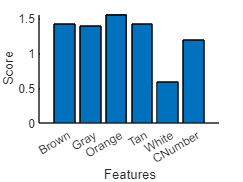


% Visualize feature scores
bar(scores)
set(gca, 'XTick', 1:length(features), 'XTickLabel', features)
xlim([0 length(features)+1])
xlabel('Features')
ylabel('Score')
box off

An iterative method is to remove the lowest performing feature and test the goodness of fit after training without the feature. The iterative method continues to remove features until the test score drops.

## Activities 

**Equipment Health Monitoring **

The first and second derivatives of the temperature are calculated as features to classify when the [TCLab](https://apmonitor.com/heat.htm) heater is on or off in the case study for [equipment health monitoring](https://apmonitor.com/pds/index.php/Main/AutomotiveMonitoring). 

**Crystal Structure Prediction**

Physical and chemical properties of the Lithium-ion silicate cathodes predict the [crystal structure of a Lithium-ion battery](https://apmonitor.com/pds/index.php/Main/LithiumIonBatteries) material as monoclinic, orthorhombic and triclinic. This case study demonstrates how feature engineering improves the classification results.